% Null hypothesis: The drug has no effect on the physiological variable.
v_drugs20 = load('drugs20.txt'); 
v_placebo20 = load('placebo20.txt'); 
[~, p_value_20] = ttest2(v_drugs20, v_placebo20, 'tail', 'right')

p_value_20 = 2.5081e-13

% p_value_20 = 2.5081e-13 << 0.05, so we reject the null hypothesis.
% The drug has a statistically significant effect in increasing the physiological variable.

v_drugs30 = load('drugs30.txt');
v_placebo30 = load('placebo30.txt'); 
[~, p_value_30] = ttest2(v_drugs30, v_placebo30, 'tail', 'right')

p_value_30 = 0.5913

% p_value_30 = 0.5913 >> 0.05, so we fail to reject the null hypothesis. 
% The drug has no statistically significant effect in increasing the physiological variable.

all_drugs = [v_drugs20; v_drugs30]; 
all_placebo = [v_placebo20; v_placebo30];
n_iterations = 10000;
alpha = 0.05;

bootstrap_estimates = zeros(n_iterations, 1);
for i = 1:n_iterations
    resampled_drug = datasample(all_drugs, 20);
    resampled_placebo = datasample(all_placebo, 20);
    bootstrap_estimates(i) = (mean(resampled_drug) - mean(resampled_placebo)) / mean(resampled_placebo) * 100;
end
bCI = quantile(bootstrap_estimates, [alpha/2, 1-alpha/2]);
fprintf('95%% Confidence Interval: [%.2f, %.2f]\n',bCI(1), bCI(2));

95% Confidence Interval: [1.67, 20.98]


clf
% Create a histogram of the bootstrap percentage differences
histogram(bootstrap_estimates, 'Normalization', 'pdf');
hold on;

% Add lines to indicate the 95% confidence interval
y_limits = ylim;
plot([bCI(1), bCI(1)], y_limits, '--r', 'LineWidth', 2);
plot([bCI(2), bCI(2)], y_limits, '--r', 'LineWidth', 2);

% Add labels and title
xlabel('Percentage Difference');
ylabel('Probability Density');
title('Bootstrap Distribution of Percentage Differences and 95% Confidence Interval');

% Add a legend
legend('Bootstrap Distribution', '95% Confidence Interval', 'Location', 'best');

% ---------------------------------
all_data = [all_drugs; all_placebo];

clf
histogram(all_data, 'Normalization', 'pdf', 'NumBins', 17)

mix_normal_pdf = @(x, mu1, sigma1, mu2, sigma2, p) ...
    p * normpdf(x, mu1, sigma1) + (1 - p) * normpdf(x, mu2, sigma2);

% Initial guesses for the parameters
mu1_init = mean(all_data) - 0.5 * std(all_data);
sigma1_init = std(all_data);
mu2_init = mean(all_data) + 0.5 * std(all_data);
sigma2_init = std(all_data);
p_init = 0.5;

init_params = [mu1_init, sigma1_init, mu2_init, sigma2_init, p_init];

% Fit the distribution using maximum likelihood estimation
params = mle(all_data, 'pdf', mix_normal_pdf, 'start', init_params);


% Create a gmdistribution object
mu = [params(1), params(3)]'; % means of the two normal distributions
sigma = cat(3, params(2)^2, params(4)^2); % covariance matrices
p = [params(5), 1 - params(5)]; % mixing proportions
gm = gmdistribution(mu, sigma, p);

x_values = linspace(4, 13, 1000)';
y_values = pdf(gm, x_values);

clf
subplot(2,2,1)
histogram(all_data, 'Normalization', 'pdf', 'NumBins',15)
hold on;
plot(x_values, y_values, 'LineWidth', 2);
title('Probability Density Function')
xlabel('Physiological Variable');
ylabel('PDF');
legend('Data', 'Fitted Distribution', 'Location', 'northoutside')

subplot(2,2,2)
exp_cdf = cdf(gm, x_values);
stairs(x_values, exp_cdf, '-r', 'LineWidth', 2)
hold on
[exp_ecdf, x] = ecdf(all_data);
stairs(x, exp_ecdf, '.-k', 'LineWidth',2)
legend('theoretical CDF', 'empirical CDF', 'Location','northoutside')
title('Cumulative Density Function') % title for plot
xlabel('Outcomes') % x-axis label
ylabel('CDF')

subplot(2,2,[3,4])
pp = 0: 0.01: 1;
samples = random(gm, 1000);
theor_q = quantile(samples, pp);
empir_q = quantile(all_data, pp);
plot(theor_q, empir_q, 's', 'MarkerSize', 10)
hold on
plot(theor_q, theor_q, '-','HandleVisibility','off')
title('Q-Q plot')
xlabel('Theoretical quantiles')
ylabel('Empirical quantiles') 

% ---------------- Question 2(a) ----------------
load('walk_data1.txt')
load('walk_data2.txt')
time = (1 : length(walk_data1))';

clf
plot(time, walk_data1,'LineWidth',2)
hold on 
plot(time, walk_data2, 'LineWidth',2)
xlabel('Time (s)')
ylabel('x(t)')
legend('Walk Data 1', 'Walk Data 2', 'Location','northwest')

% ---------------- Question 2(b) ----------------
lagged_walk1 = [0; walk_data1(1:length(walk_data1)-1)];
data = table(time, walk_data1, lagged_walk1, 'VariableNames', {'Time', 'x', 'x_lagged'});
m1 = fitlm(data, 'x~x_lagged');

% plot distribution of residuals (for outliers etc.)
clf
subplot(2,2,1)
% plot the raw data:
plot(time,walk_data1,'.', 'MarkerSize', 5)
hold on
% plot model fit line using the estimates parameters:
xx = 1:length(walk_data1);
yy = zeros(length(xx), 1);
yy(1) = m1.Coefficients{1,1};
for i = 2:length(yy)
    yy(i) = yy(i-1) * m1.Coefficients{2,1} + m1.Coefficients{1,1};
end

plot(xx,yy,'k','LineWidth',1.5)
xlabel('Time (s)')
ylabel('x(t)')
title('Model fit line')
subplot(2,2,2)
plotResiduals(m1)
subplot(2,2,3)
plotResiduals(m1,'fitted')
subplot(2,2,4)
plotResiduals(m1,'lagged')

% Discussion of model fit and residual plots:
% Visually, the model fit line somewhat captures the downward trend of the data. However, there is a noticeable variation in the data that the model fit does not capture.
% The distribution of residuals does not resemble a normal distribution. It appears to be trimodal with multiple peaks occurring at around -10, 0, and 10. This indicates that the model does not account for some underlying patterns.
% The plot of residuals vs fitted values shows an even distribution on either side of zero, suggesting that homoscedasticity holds true. It does not take a rectangular form, but that can be explained by the autocorrelation of the equation (which reduces the variation in fitted values).
% Plotting residuals versus lagged residuals shows strong evidence of autocorrelation in the residuals. This is not surprising, as in the spatial random process, a lagged component forms part of the equation. Consecutive readings are not independent.
% Overall, we must be cautious when interpreting this model fit to the data. Some model assumptions clearly do not hold. This means that the theory we use may yield misleading results.rall, we have to be very careful with interpreting this model fit to the data. Some model assumptions clearly do not hold. This means that the theory we use may give miselading results.


% ---------------- Question 2(b) ----------------
lagged_walk2 = [0; walk_data2(1:length(walk_data2)-1)];
data = table(time, walk_data2, lagged_walk2, 'VariableNames', {'Time', 'x', 'x_lagged'});
m2 = fitlm(data, 'x~x_lagged');

% plot model fit line using the estimates parameters:
xx = 1:length(time);
yy = zeros(length(xx), 1);
yy(1) = m2.Coefficients{1,1};
for i = 2:length(yy)
    yy(i) = yy(i-1) * m2.Coefficients{2,1} + m2.Coefficients{1,1};
end

% xx = [min(time) max(time)];
% yy = [m2.Coefficients{1,1}+min(time)*m2.Coefficients{2,1} m2.Coefficients{1,1}+max(time)*m2.Coefficients{2,1}];
% plot distribution of residuals (for outliers etc.)
clf
subplot(2,2,1)
% plot the raw data:
plot(time,walk_data2,'.', 'MarkerSize', 10)
hold on
plot(xx,yy,'k','LineWidth',1.5)
xlabel('Time (s)')
ylabel('x(t)')
title('Model fit line')
subplot(2,2,2)
plotResiduals(m2)
subplot(2,2,3)
plotResiduals(m2,'fitted')
subplot(2,2,4)
plotResiduals(m2,'lagged') 

% Discussion of model fit and residual plots:
% TODO

% ---------------- Question 2(c) ----------------
% TODO

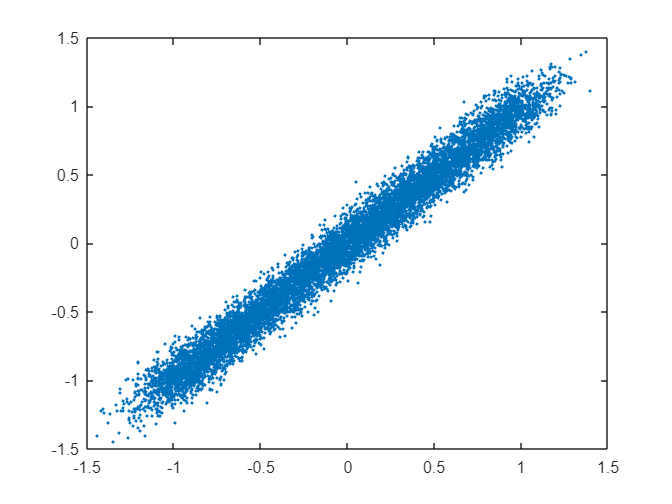

% ---------------- Question 2(d) ----------------
% Parameters
n_time_increments = 10000;
sigma = 0.1;
x = zeros(1, n_time_increments);
x(1) = 0;

% Random walk simulation
for t = 2:n_time_increments
    if abs(x(t - 1)) < 1
        mu = 0;
    else
        mu = -0.05 * x(t - 1);
    end
    
    theta = normrnd(mu, sigma);
    x(t) = x(t - 1) + theta;
end
time = 1:n_time_increments;
lagged_x = [0, x(1:length(x)-1)];
clf
plot(x, lagged_x, '.')

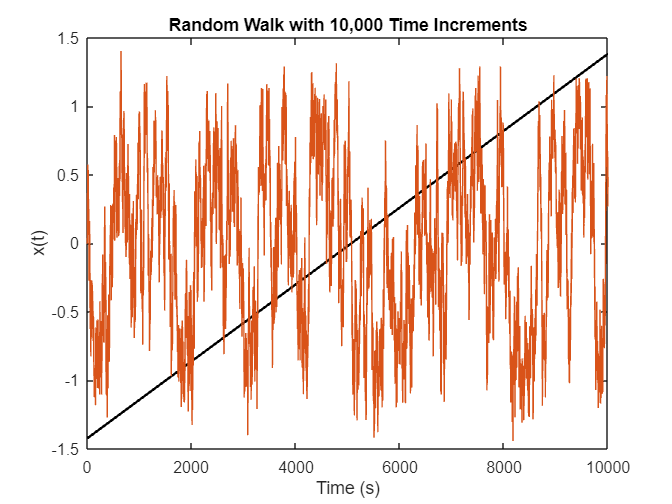

data = table(time', x', lagged_x', 'VariableNames', {'Time', 'x', 'lagged_x'});
m1 = fitlm(data, 'x~lagged_x');
% plot model fit line using the estimates parameters:
clf
xx = [1 n_time_increments];
yy = [m1.Coefficients{1,1}+min(x)*m1.Coefficients{2,1} m1.Coefficients{1,1}+max(x)*m1.Coefficients{2,1}];
plot(xx,yy,'k','LineWidth',1.5)
hold on
plot(1:n_time_increments, x);
xlabel('Time (s)');
ylabel('x(t)')
title('Random Walk with 10,000 Time Increments');

% Parameters
n_time_increments = 10000;
delta_t = 1;
x = zeros(1, n_time_increments);
x(1) = 0;

% Random walk simulation
for t = 2:n_time_increments
    mu = 0;
    sigma = 0.1 * abs(x(t - 1));
    theta = mu + sigma * randn(1);
    x(t) = x(t - 1) + theta;
end
clf
% Plot the random walk
plot(1:n_time_increments, x);
xlabel('Time (s)');
ylabel('Position (m)');
title('Random Walk with Non-constant Variance');